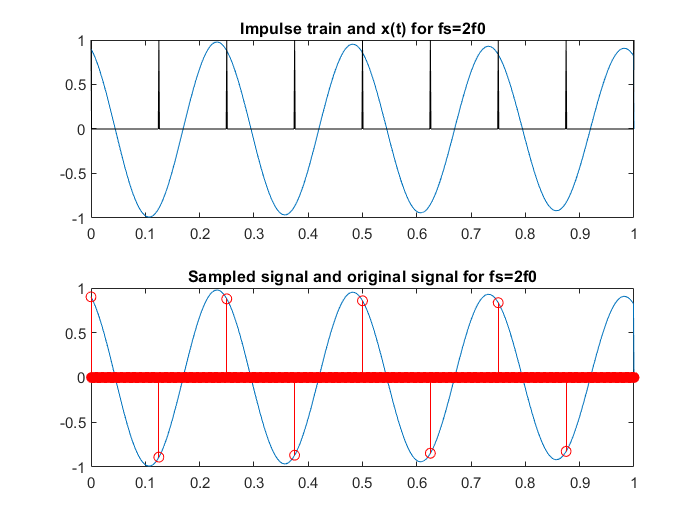

clc
clear
close all

Fsinf=1000;
delt=1/Fsinf;
f0=4;
t=0:delt:1;
xt=exp(-0.1*t).*cos(2*pi*f0*t + pi/7).*(unit(t)-unit(t-1));

% Sampling 
Fs1=2*f0;
T1=1/Fs1;
pt1=zeros(size(t));
pt1(rem(t,T1)==0)=1;

%For Fs=2f0
xpt1=xt.*pt1;
subplot(2,1,1);
plot(t,xt);title('Impulse train and x(t) for fs=2f0');
hold on;
plot(t,pt1,'k');
subplot(2,1,2);
plot(t,xt);title('Sampled signal and original signal for fs=2f0');
hold on;
stem(t,xpt1,'r');

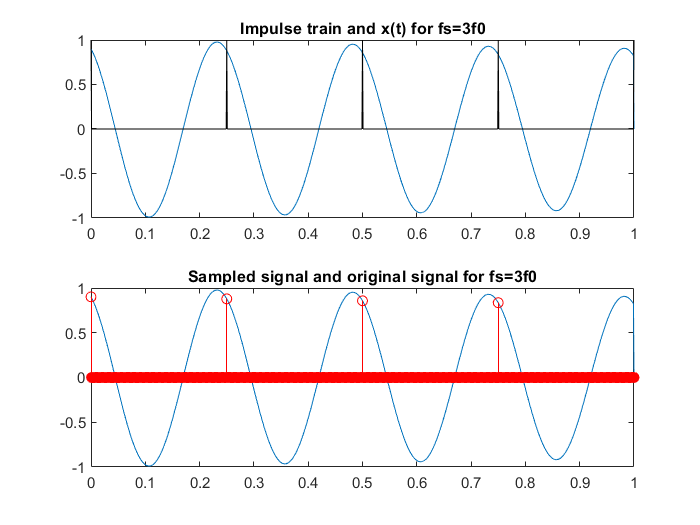


figure;

%For Fs=3f0
Fs2=3*f0;
T2=1/Fs2;
pt2=zeros(size(t));
pt2(rem(t,T2)==0)=1;

xpt2=xt.*pt2;
subplot(2,1,1);
plot(t,xt);title('Impulse train and x(t) for fs=3f0');
hold on;
plot(t,pt2,'k');
subplot(2,1,2);
plot(t,xt);title('Sampled signal and original signal for fs=3f0');
hold on;
stem(t,xpt2,'r');

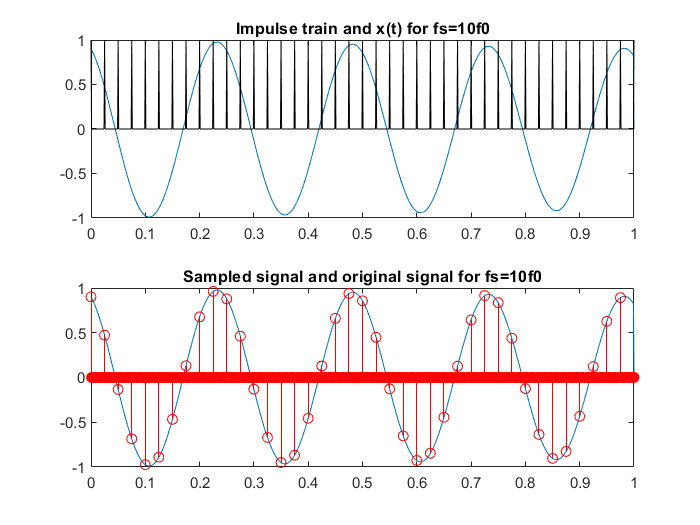


figure;

%For Fs=10f0
Fs3=10*f0;
T3=1/Fs3;
pt3=zeros(size(t));
pt3(rem(t,T3)==0)=1;

xpt3=xt.*pt3;
subplot(2,1,1);
plot(t,xt);title('Impulse train and x(t) for fs=10f0');
hold on;
plot(t,pt3,'k');
subplot(2,1,2);
plot(t,xt);title('Sampled signal and original signal for fs=10f0');
hold on;
stem(t,xpt3,'r');